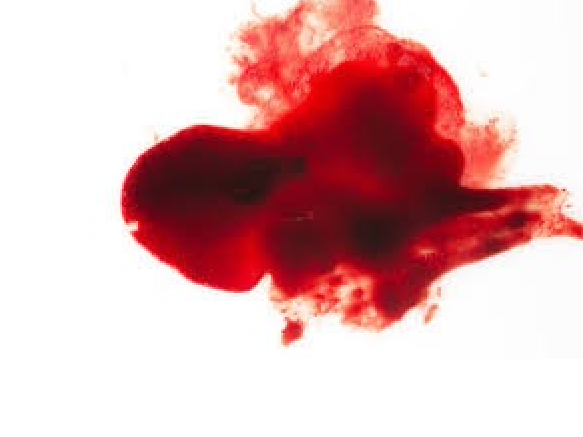

%1. IMAGE ACQUISITION 

% Step 1: Clear Workspace and Close Figures
clear; clc; close all;

% Step 2: Load Image
img1 = imread('/MATLAB Drive/DIP/dip1.jpeg');
img2 = imread('/MATLAB Drive/DIP/dip2.jpeg');
% Step 3: Display Original Image
figure; imshow(img1); title('Original Image');

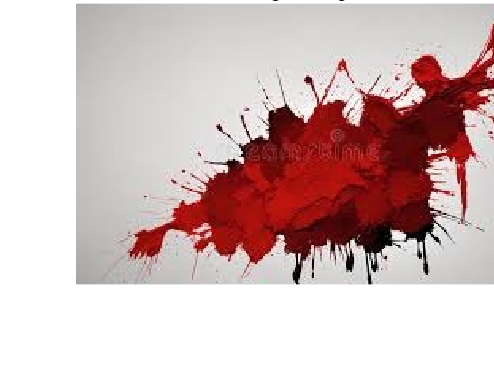

figure; imshow(img2); title('Original Image');

% Step 4: Resize Image for Consistency
img1 = imresize(img1, [512, 512]);
img2 = imresize(img2, [512, 512]);
% Step 5: Convert Image to Grayscale
grayImg1 = rgb2gray(img1);
grayImg2 = rgb2gray(img2);
% Step 6: Verify Dimensions of Grayscale Image
disp(size(grayImg1));

   512   512



disp(size(grayImg2));

   512   512



% Step 7: Save Grayscale Image (Optional)
imwrite(grayImg1, 'processed_grayscale.jpg');
imwrite(grayImg2, 'processed_grayscale.jpg');
% Step 8: Verify Pixel Intensity Range
disp(['Intensity Range: ', num2str(min(grayImg1(:))), '-', num2str(max(grayImg1(:)))]);

Intensity Range: 23-255


disp(['Intensity Range: ', num2str(min(grayImg2(:))), '-', num2str(max(grayImg2(:)))]);

Intensity Range: 0-255


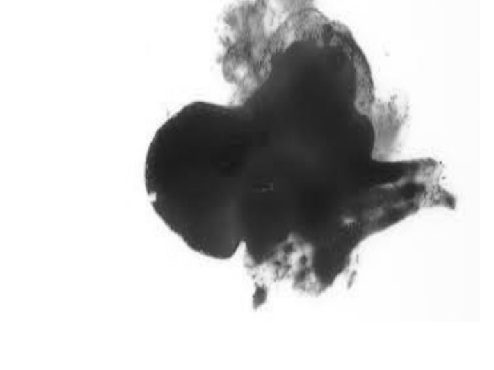

% Step 9: Display Grayscale Image
figure; imshow(grayImg1); title('Grayscale Image');

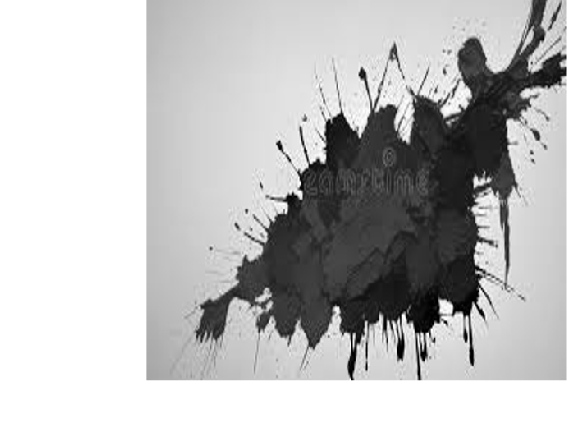

figure; imshow(grayImg2); title('Grayscale Image');

% Step 10: Complete Acquisition Process
disp('Image Acquisition Completed.');

Image Acquisition Completed.


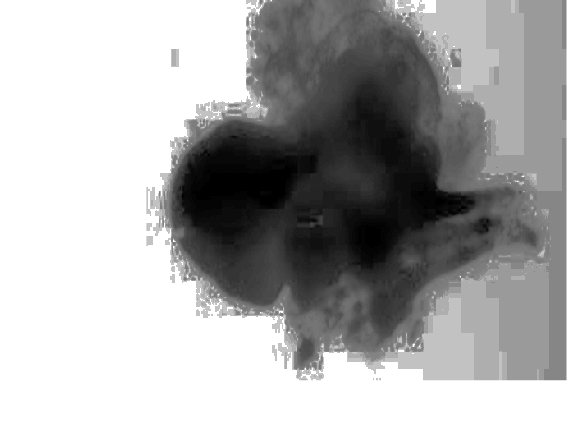



%2.IMAGE PREPROCESSING
% Step 1: Histogram Equalization
eqImg = histeq(grayImg1);

% Step 2: Display Equalized Image
figure; imshow(eqImg); title('Histogram Equalized Image');

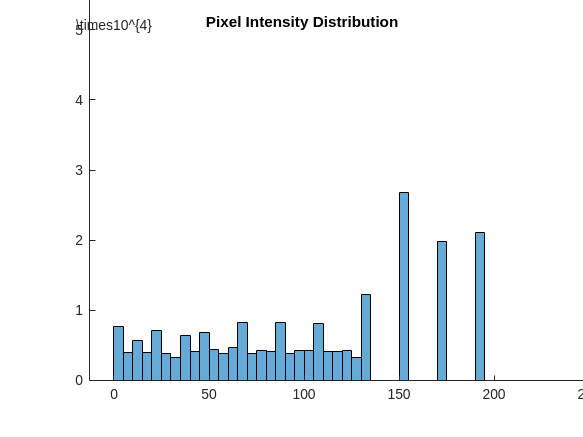


% Step 3: Apply Median Filtering for Noise Reduction
filteredImg = medfilt2(eqImg, [3 3]);

% Step 4: Detect Edges Using Canny Edge Detector
edges = edge(filteredImg, 'Canny');

% Step 5: Plot Histogram of Pixel Intensities
figure; histogram(eqImg(:)); title('Pixel Intensity Distribution');

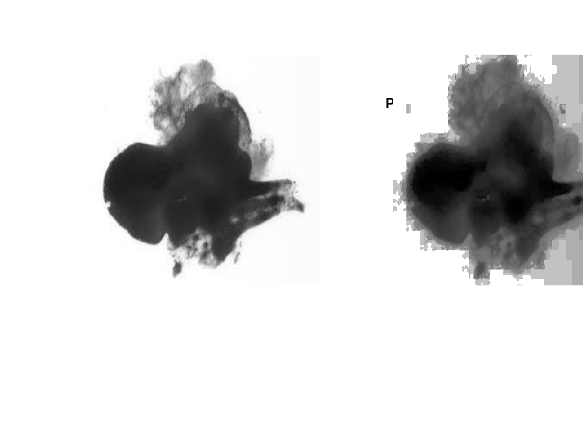


% Step 6: Remove Small Noise Using Morphological Operations
cleanedImg = imopen(filteredImg, strel('disk', 2));

% Step 7: Compare Original and Preprocessed Images
figure;
subplot(1, 2, 1); imshow(grayImg1); title('Original');
subplot(1, 2, 2); imshow(cleanedImg); title('Preprocessed');


% Step 8: Save Preprocessed Image (Optional)
imwrite(cleanedImg, 'preprocessed_image.jpg');

% Step 9: Display Edge Detected Image
figure; imshow(edges); title('Edge Detection');


% Step 10: Complete Preprocessing Step
disp('Preprocessing Completed.');

Preprocessing Completed.





%3.SEGMENTATION
% Step 1: Convert Preprocessed Image to Binary
bwImg = imbinarize(cleanedImg, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.5);

% Step 2: Perform Morphological Opening
bwImg = imopen(bwImg, strel('disk', 3));

% Step 3: Fill Holes in Binary Image
filledImg = imfill(bwImg, 'holes');

% Step 4: Label Connected Components
[labeledImg, num] = bwlabel(filledImg);

% Step 5: Display Number of Detected Regions
disp(['Number of Bloodstains Detected: ', num2str(num)]);

Number of Bloodstains Detected: 6



% Step 6: Outline Detected Regions on Original Image
outlineImg = bwperim(filledImg);
outlinedOverlay = img1;
outlinedOverlay(repmat(outlineImg, [1, 1, 3])) = 255;

% Step 7: Show Segmented Image
figure; imshow(outlinedOverlay); title('Segmented Bloodstains');


% Step 8: Save Segmented Image (Optional)
imwrite(outlinedOverlay, 'segmented_bloodstains.jpg');

% Step 9: Display Labeled Regions
figure; imshow(label2rgb(labeledImg)); title('Labeled Bloodstains');


% Step 10: Complete Segmentation Step
disp('Segmentation Completed.');

Segmentation Completed.



%4.FEATURE EXTRACTION
% Step 1: Extract Region Properties
stats = regionprops(filledImg, 'Area', 'Perimeter', 'Eccentricity', 'Centroid', 'BoundingBox');

% Step 2: Initialize Feature Table
featuresTable = array2table(zeros(length(stats), 4), 'VariableNames', {'Area', 'Perimeter', 'Eccentricity', 'Circularity'});

% Step 3: Loop Through Each Region
for i = 1:length(stats)
    % Step 4: Calculate Geometric Features
    featuresTable.Area(i) = stats(i).Area;
    featuresTable.Perimeter(i) = stats(i).Perimeter;
    featuresTable.Eccentricity(i) = stats(i).Eccentricity;
    
    % Step 5: Compute Circularity
    featuresTable.Circularity(i) = (4 * pi * stats(i).Area) / (stats(i).Perimeter^2);
end

% Step 6: Display Extracted Features
disp('Extracted Features:');

Extracted Features:


disp(featuresTable);

       Area       Perimeter    Eccentricity    Circularity
    __________    _________    ____________    ___________

    2.4873e+05     3564.3        0.26223         0.24603  
            30     17.276        0.55277          1.2631  
            25     15.316              0          1.3392  
            40     21.196        0.78062          1.1188  
            25     15.316              0          1.3392  
            25     15.316              0          1.3392  



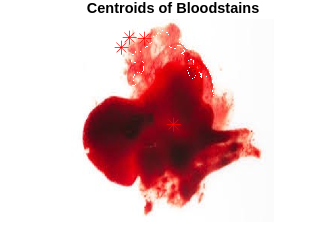


% Step 7: Highlight Centroids on Image
centroids = cat(1, stats.Centroid);
figure; imshow(outlinedOverlay); hold on;
plot(centroids(:,1), centroids(:,2), 'r*', 'MarkerSize', 10); hold off;
title('Centroids of Bloodstains');

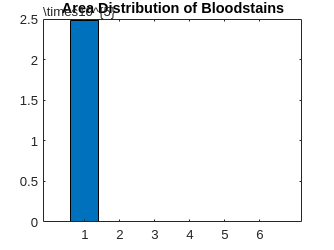


% Step 8: Save Features to File (Optional)
writetable(featuresTable, 'bloodstain_features.csv');

% Step 9: Visualize Feature Distribution
figure; bar(featuresTable.Area); title('Area Distribution of Bloodstains');


% Step 10: Complete Feature Extraction Step
disp('Feature Extraction Completed.');

Feature Extraction Completed.




%5.CLASSIFICATION 

% Step 1: Prepare Data for Classification
X = table2array(featuresTable(:, {'Area', 'Perimeter', 'Eccentricity', 'Circularity'}));
y = randi([0, 1], size(X, 1), 1); % Simulate labels for binary classification (0/1)

% Step 2: Split Data into Training and Testing Sets
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
trainIdx = training(cv);
testIdx = test(cv);

X_train = X(trainIdx, :);
y_train = y(trainIdx);
X_test = X(testIdx, :);
y_test = y(testIdx);

% Step 3: Train Support Vector Machine (SVM) Classifier
SVMModel = fitcsvm(X_train, y_train, 'KernelFunction', 'linear');

% Step 4: Evaluate Classifier on Training Data
y_train_pred = predict(SVMModel, X_train);
trainAccuracy = sum(y_train == y_train_pred) / length(y_train) * 100;
disp(['Training Accuracy: ', num2str(trainAccuracy), '%']);

Training Accuracy: 80%



% Step 5: Test Classifier on Test Data
y_test_pred = predict(SVMModel, X_test);

% Step 6: Calculate Test Accuracy
testAccuracy = sum(y_test == y_test_pred) / length(y_test) * 100;
disp(['Test Accuracy: ', num2str(testAccuracy), '%']);

Test Accuracy: 100%



% Step 7: Display Confusion Matrix
confMat = confusionmat(y_test, y_test_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

     1



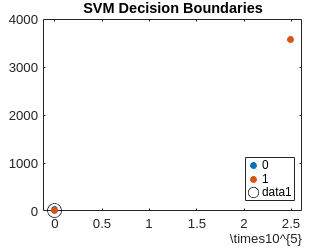


% Step 8: Visualize Decision Boundaries (2D Projection)
sv = SVMModel.SupportVectors;
figure; gscatter(X(:, 1), X(:, 2), y);
hold on;
plot(sv(:, 1), sv(:, 2), 'ko', 'MarkerSize', 10);
title('SVM Decision Boundaries');


% Step 9: Save Trained Model (Optional)
save SVMModel SVMModel;

% Step 10: Complete Classification Task
disp('Classification Completed.');

Classification Completed.





%6. TRAJECTORY AND ANGLE ANALYSIS

% Step 1: Define the Blood Stain Centroids
centroids = cat(1, stats.Centroid);

% Step 2: Define a Reference Point (e.g., origin or assumed blood source)
sourcePoint = [250, 250]; % Example reference point

% Step 3: Calculate the Vector from Source to Each Centroid
vectors = centroids - sourcePoint;

% Step 4: Compute Angles of Impact
angles = atan2d(vectors(:, 2), vectors(:, 1)); % Angles in degrees

% Step 5: Display Angles for Each Blood Stain
disp('Impact Angles:');

Impact Angles:


disp(angles);

   62.8419
 -124.2819
 -116.5651
 -107.7032
  -62.2049
  -59.6568




% Step 6: Calculate Trajectories (Distance from Source)
trajectories = sqrt(sum(vectors.^2, 2));

% Step 7: Display Trajectory Distances
disp('Trajectory Distances:');

Trajectory Distances:


disp(trajectories);

   17.7063
  214.8191
  225.8429
  210.4667
  145.8252
  142.5237



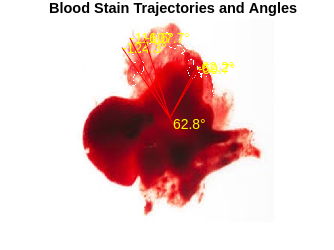


% Step 8: Plot Blood Stains and Their Trajectories
figure; imshow(outlinedOverlay); hold on;
for i = 1:length(centroids)
    plot([sourcePoint(1), centroids(i, 1)], [sourcePoint(2), centroids(i, 2)], 'r-');
    text(centroids(i, 1), centroids(i, 2), sprintf('%.1f°', angles(i)), 'Color', 'y');
end
title('Blood Stain Trajectories and Angles');
hold off;


% Step 9: Save Results (Optional)
save('Trajectory_Angles.mat', 'angles', 'trajectories');

% Step 10: Complete Trajectory Analysis
disp('Trajectory and Angle Analysis Completed.');

Trajectory and Angle Analysis Completed.
